# **ThermoGuard — CPU thermal parameter derivation**

Intel Core i5-13600K and Noctua NH-U12S redux | Research revision: 4 October 2026

**Purpose.** Establish a transparent, executable parameter set for a two-node CPU cooling model and a later PI temperature controller. Every numerical input is identified as a manufacturer specification, published benchmark, material reference, or modeling assumption. This is a literature-informed nominal model; its Intel junction-temperature dynamics have not been experimentally identified.

The document covers active cooling, a heatsink with its fan stopped, and an idealized no-heatsink comparison. Each derivation is followed by numerical output. Sections 9–12 check the consequences of the parameters; Section 13 gives the Simscape settings. References [S1]–[S7] are linked in Section 15. Run All from the top to regenerate the results using base MATLAB.

## 1. System definition and verified specifications

Intel lists Processor Base Power as 125 W, Maximum Turbo Power as 181 W, TJUNCTION as 100 °C, and package dimensions as 45.0 × 37.5 mm [S1, CPU Specifications and Package Specifications]. Here, the two powers are prescribed heat-input test cases. They are not a claim that a real CPU always dissipates either value: workload, firmware, power limits and thermal throttling affect actual power.

Noctua specifies 550 g without the fan, nickel-plated copper base/heatpipes, aluminium fins, and the NF-P12 redux-1700 PWM fan [S2, p. 1]. Its free-air flow and maximum static pressure describe different operating limits; neither can be used directly as the installed heatsink convection coefficient. Fan motor power is excluded from the CPU heat input.

CPU_model = "Intel Core i5-13600K";
cooler_model = "Noctua NH-U12S redux";
Q_base = 125;                    % [W], Intel [S1]
Q_turbo = 181;                   % [W], Intel [S1]
Tj_max = 100;                    % [degC], Intel [S1]
L_cpu = 45e-3; W_cpu = 37.5e-3;  % [m], package outline, not IHS area
m_hs = 0.550;                    % [kg], heatsink without fan [S2]
RPM_max = 1700;                  % [rpm], nominal maximum, +/-10% [S2]
Vdot_max = 120.2;                % [m^3/h], free-air maximum [S2]
dp_max = 2.83;                   % [mmH2O], maximum static pressure [S2]
P_fan_max = 1.08;                % [W], maximum input, not typical [S2]

cpuData = table( ...
    ["Processor base power"; "Maximum turbo power"; "Junction limit"; ...
     "Package length"; "Package width"; "Heatsink mass (no fan)"; ...
     "Maximum fan speed"; "Maximum free-air flow"; ...
     "Maximum static pressure"; "Maximum fan input power"], ...
    [Q_base; Q_turbo; Tj_max; L_cpu*1e3; W_cpu*1e3; m_hs; ...
     RPM_max; Vdot_max; dp_max; P_fan_max], ...
    ["W"; "W"; "degC"; "mm"; "mm"; "kg"; "rpm"; "m^3/h"; "mmH2O"; "W"], ...
    [repmat("S1: Intel",5,1); repmat("S2: Noctua",5,1)], ...
    'VariableNames', {'Parameter','Value','Unit','Source'});
disp(CPU_model + " / " + cooler_model)

Intel Core i5-13600K / Noctua NH-U12S redux


cpuData

cpuData = 10×4 table
            Parameter            Value     Unit         Source   
    _________________________    _____    _______    ____________

    "Processor base power"         125    "W"        "S1: Intel" 
    "Maximum turbo power"          181    "W"        "S1: Intel" 
    "Junction limit"               100    "degC"     "S1: Intel" 
    "Package length"                45    "mm"       "S1: Intel" 
    "Package width"               37.5    "mm"       "S1: Intel" 
    "Heatsink mass (no fan)"      0.55    "kg"       "S2: Noctua"
    "Maximum fan speed"           1700    "rpm"      "S2: Noctua"
    "Maximum free-air flow"      120.2    "m^3/h"    "S2: Noctua"
    "Maximum static pressure"     2.83    "mmH2O"    "S2: Noctua"
    "Maximum fan input power"     1.08    "W"        "S2: Noctua"


Package outline dimensions are retained for identification, not used as the exposed heat-spreader area.

## 2. Thermal network and governing equations

**Temperature nodes.** Te is an effective CPU junction-temperature state; Th is the lumped heatsink temperature; Ta is the air temperature entering the cooler. Th is not the processor case temperature. Reh combines die/package, thermal interface and contact effects between these chosen nodes. Rha(u) is the effective heatsink-to-air resistance.

`Q(t) → CPU (Te, Ce) ── Reh ── heatsink (Th, Ch) ── Rha(u) ── air (Ta)`

`qeh = (Te − Th) / Reh;     qha = G(u) (Th − Ta); G(u) = 1 / Rha(u)`

`Ce dTe/dt = Q(t) − qeh;     Ch dTh/dt = qeh − qha`

Adding the two balances gives Ce dTe/dt + Ch dTh/dt = Q − qha: the internal CPU-to-heatsink heat flow cancels. Capacitances [J/K] control stored energy and transient speed. Resistances [K/W] control temperature drops per watt; conductances [W/K] are their reciprocals. Temperature differences have the same numerical value in K and °C. Simscape absolute temperatures are supplied in kelvin.

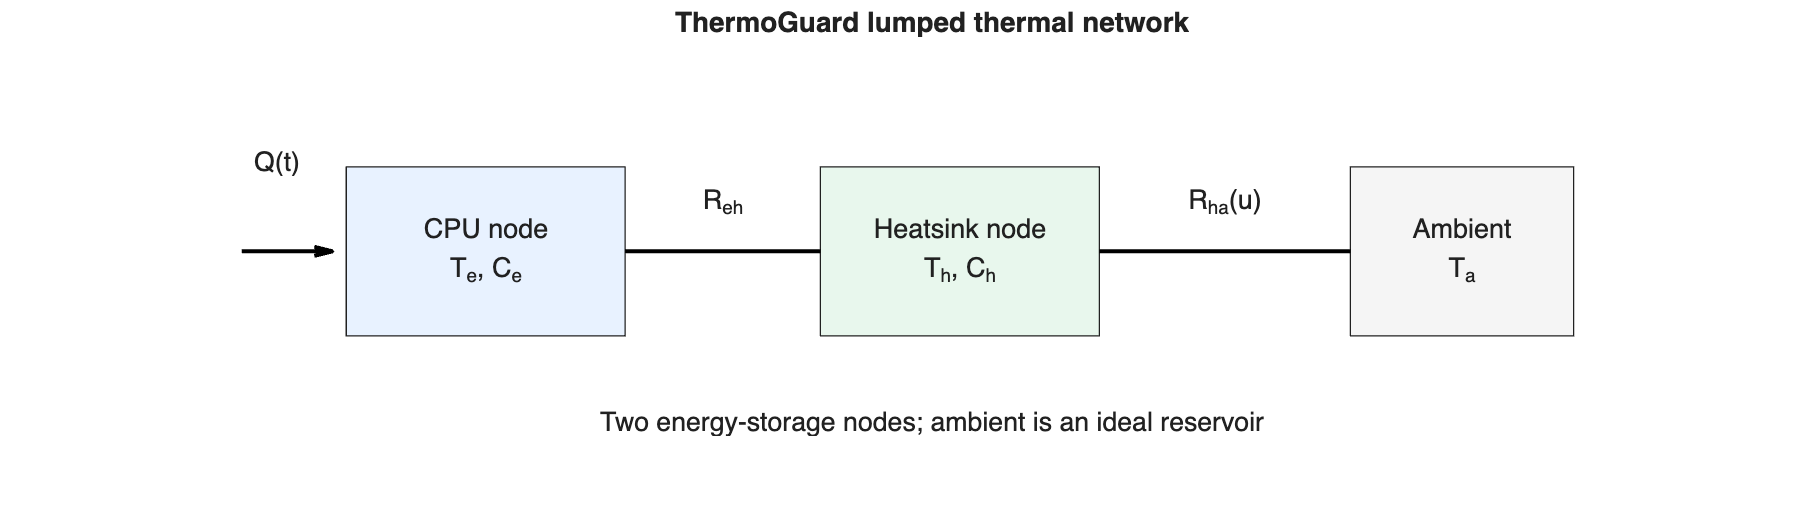

figure('Name','Thermal network','Color','w','Position',[100 100 900 260]);
theme(gcf,'light');
axis([0 10 0 3]); axis off
rectangle('Position',[0.8 0.9 2.0 1.2],'FaceColor',[0.91 0.95 1]);
rectangle('Position',[4.2 0.9 2.0 1.2],'FaceColor',[0.91 0.97 0.93]);
rectangle('Position',[8.0 0.9 1.6 1.2],'FaceColor',[0.96 0.96 0.96]);
text(1.8,1.5,{'CPU node','T_e, C_e'},'HorizontalAlignment','center');
text(5.2,1.5,{'Heatsink node','T_h, C_h'},'HorizontalAlignment','center');
text(8.8,1.5,{'Ambient','T_a'},'HorizontalAlignment','center');
hold on
plot([2.8 4.2],[1.5 1.5],'k-','LineWidth',1.5);
plot([6.2 8.0],[1.5 1.5],'k-','LineWidth',1.5);
quiver(0.05,1.5,0.65,0,0,'k','LineWidth',1.5,'MaxHeadSize',0.6);
text(0.3,2.15,'Q(t)','HorizontalAlignment','center');
text(3.5,1.85,'R_{eh}','HorizontalAlignment','center');
text(7.1,1.85,'R_{ha}(u)','HorizontalAlignment','center');
text(5,0.3,'Two energy-storage nodes; ambient is an ideal reservoir', ...
    'HorizontalAlignment','center');
title('ThermoGuard lumped thermal network');
hold off

## 3. Explicit modelling assumptions and initial conditions    

The one-node CPU approximation cannot resolve die-to-IHS gradients or individual core hot spots. The heatsink node also neglects internal gradients and heatpipe dynamics. These simplifications are useful for initial control studies, but their validity must be checked against the timescale and temperature measurement used in a real experiment.

T_a = 25;                      % [degC], assumed cooler-inlet temperature
T_e0 = T_a; T_h0 = T_a;        % Cold-start comparison

assumptionData = table( ...
    ["Heat input"; "Ambient"; "CPU and heatsink"; "Material properties"; ...
     "Other heat paths"; "Radiation"; "Fan dynamics"; "Thermal protection"], ...
    ["All prescribed CPU power becomes heat"; "Constant 25 degC"; ...
     "One uniform-temperature node each"; "Constant reference specific heats"; ...
     "Motherboard/socket losses omitted"; "Included only implicitly in effective losses"; ...
     "Instantaneous effective cooling command"; "Record first 100 degC crossing"], ...
    ["Use measured package power for later identification"; ...
     "Measure local inlet air, not just room temperature"; ...
     "Fast die and internal heatsink gradients unresolved"; ...
     "Composition and temperature dependence remain uncertain"; ...
     "Most questionable when cooler is absent"; ...
     "Do not add a separate radiative path to a fitted total twice"; ...
     "PWM/RPM/airflow-to-conductance mapping is not identified"; ...
     "No throttling or shutdown dynamics are simulated"], ...
    'VariableNames', {'Topic','Assumption','Implication'});
assumptionData

assumptionData = 8×3 table
            Topic                              Assumption                                               Implication                          
    _____________________    ______________________________________________    ______________________________________________________________

    "Heat input"             "All prescribed CPU power becomes heat"           "Use measured package power for later identification"         
    "Ambient"                "Constant 25 degC"                                "Measure local inlet air, not just room temperature"          
    "CPU and heatsink"       "One uniform-temperature node each"               "Fast die and internal heatsink gradients unresolved"         
    "Material properties"    "Constant reference specific heats"               "Composition and temperature dependence remain uncertain"     
    "Other heat paths"       "Motherboard/socket losses omitted"               "Most questionable when cooler is absent"

## 4. Material properties and unit conversion

The Engineering ToolBox table [S4, rows Aluminium, Copper and Silicon] gives 0.91, 0.39 and 0.71 kJ/(kg·K). Multiplication by 1000 gives the J/(kg·K) values below. These are rounded engineering reference values used as constants, not measurements of the CPU or cooler alloys. Using the actual cited values replaces the earlier draft's more precise but unmatched 897/385/705 values.

cp_Al = 0.91 * 1000;           % [J/(kg*K)], reference value [S4]
cp_Cu = 0.39 * 1000;           % [J/(kg*K)], reference value [S4]
cp_Si = 0.71 * 1000;           % [J/(kg*K)], reference value [S4]
materialData = table(["Aluminium"; "Copper"; "Silicon"], ...
    [cp_Al; cp_Cu; cp_Si], repmat("J/(kg*K)",3,1), ...
    repmat("S4: reference approximation",3,1), ...
    'VariableNames', {'Material','SpecificHeat','Unit','Basis'});
materialData

materialData = 3×4 table
     Material      SpecificHeat       Unit                   Basis            
    ___________    ____________    __________    _____________________________

    "Aluminium"        910         "J/(kg*K)"    "S4: reference approximation"
    "Copper"           390         "J/(kg*K)"    "S4: reference approximation"
    "Silicon"          710         "J/(kg*K)"    "S4: reference approximation"


## 5. Heatsink thermal capacitance

For materials sharing one temperature, Ch = Σ mi cpi. Approximating the heatsink as only aluminium and copper gives Ch = mhs [fAl cpAl + (1 − fAl) cpCu], where fAl is the aluminium mass fraction. Noctua supplies the total mass and material names, but not that mass fraction [S2]. Nickel plating, heatpipe working fluid and small fittings are neglected in this approximation.

The all-copper and all-aluminium values are limiting values only within this two-material approximation. A nominal fAl = 0.5 is an explicit illustrative choice, not a measured composition or a statistically expected value. The full 0–1 range is carried into the sensitivity study.

f_Al = 0.50;                   % Assumed aluminium mass fraction
C_h_min = m_hs * cp_Cu;
C_h_max = m_hs * cp_Al;
C_h_nominal = m_hs * (f_Al*cp_Al + (1-f_Al)*cp_Cu);
heatsinkCapacitance = table(["All copper proxy"; "50/50 nominal"; "All aluminium proxy"], ...
    [0; f_Al; 1], [C_h_min; C_h_nominal; C_h_max], ...
    'VariableNames', {'Case','AluminiumMassFraction','Capacitance_J_per_K'});
heatsinkCapacitance

heatsinkCapacitance = 3×3 table
            Case             AluminiumMassFraction    Capacitance_J_per_K
    _____________________    _____________________    ___________________

    "All copper proxy"                  0                    214.5       
    "50/50 nominal"                   0.5                    357.5       
    "All aluminium proxy"               1                    500.5       


fprintf('Nominal heatsink capacitance: %.1f J/K\n', C_h_nominal);

Nominal heatsink capacitance: 357.5 J/K


## 6. CPU thermal capacitance: an uncertain effective parameter

No effective junction-node capacitance was found in the Intel specification [S1]. The earlier draft's 35.5 g processor mass could not be substantiated from the reviewed sources. It is retained here only as an explicitly assumed mass for a dimensional, order-of-magnitude estimate, not described as published product data.

`Ce,nominal = mCPU,assumed (cpCu + cpSi) / 2`

This reproduces the original estimation method transparently. Neither the copper nor silicon calculation is a rigorous bound for the multi-material CPU package. A junction node can involve only part of the package mass during a fast transient. Consequently, the sensitivity study varies effective Ce by 0.5× to 2× its nominal value; that range is an author-selected stress test, not a confidence interval or a claim to cover every possible junction response.

m_cpu_assumed = 0.0355;         % [kg], unverified assumption from earlier draft
C_e_Cu_proxy = m_cpu_assumed * cp_Cu;
C_e_Si_proxy = m_cpu_assumed * cp_Si;
C_e_nominal = (C_e_Cu_proxy + C_e_Si_proxy)/2;
C_e_sensitivity = C_e_nominal * [0.5 1 2];
cpuCapacitance = table( ...
    ["Copper material proxy"; "Nominal midpoint"; "Silicon material proxy"; ...
     "Sensitivity low"; "Sensitivity high"], ...
    [C_e_Cu_proxy; C_e_nominal; C_e_Si_proxy; C_e_sensitivity(1); C_e_sensitivity(3)], ...
    'VariableNames', {'Case','Capacitance_J_per_K'});
cpuCapacitance

cpuCapacitance = 5×2 table
              Case              Capacitance_J_per_K
    ________________________    ___________________

    "Copper material proxy"           13.845       
    "Nominal midpoint"                19.525       
    "Silicon material proxy"          25.205       
    "Sensitivity low"                 9.7625       
    "Sensitivity high"                 39.05       


fprintf('Nominal effective CPU capacitance: %.3f J/K (assumption-based)\n',C_e_nominal);

Nominal effective CPU capacitance: 19.525 J/K (assumption-based)


To identify Ce, fit a measured power-step temperature response with the chosen temperature sensor and model structure. A measured package mass alone would not establish junction dynamics. Ce affects initial heating and fast response; Ch predominantly affects the slower energy-storage response.

## 7. Published cooler benchmarks and the resistance split

GamersNexus reports the following approximate temperature rises at 100% fan speed [S3, the 65 W, 123 W and 200 W full-speed sections and CPU Cooler Test Bench]. The benchmark CPUs are different. These rows must not be fitted as three power points of one fixed CPU/cooler network.

Q_benchmark = [65; 123; 200];
DeltaT_benchmark = [38; 58; 62];  % [K], rounded article text [S3]
R_benchmark = DeltaT_benchmark ./ Q_benchmark;
benchmarkData = table( ...
    ["Ryzen 5 3600"; "Ryzen 7 3800X"; "Ryzen 9 3950X"], ...
    Q_benchmark, DeltaT_benchmark, R_benchmark, ...
    'VariableNames', {'BenchmarkCPU','Power_W','Rise_K','EffectiveResistance_K_per_W'});
benchmarkData

benchmarkData = 3×4 table
     BenchmarkCPU      Power_W    Rise_K    EffectiveResistance_K_per_W
    _______________    _______    ______    ___________________________

    "Ryzen 5 3600"        65        38                0.58462          
    "Ryzen 7 3800X"      123        58                0.47154          
    "Ryzen 9 3950X"      200        62                   0.31          


The 200 W Ryzen 9 3950X result gives Rreference = 62/200 = 0.31 K/W. It is an effective CPU-temperature-to-air ratio for that test assembly, including its package, mount and measurement convention. Applying it to an i5-13600K is a transfer assumption. The different ratios in the other rows demonstrate why it should not be advertised as an intrinsic cooler-only resistance.

**Identifiability.** With this model at steady state, (Te − Ta)/Q = Reh + Rha. One CPU-to-air measurement therefore constrains only the sum. Intel case-temperature thermal-solution design points cannot be subtracted from an unrelated AMD CPU benchmark to isolate Reh: they use different systems and temperature reference locations. The earlier cross-system subtraction is removed.

Use an explicit allocation parameter α to create a nominal two-node network: Reh = α Rtotal and Rha,maxfan = (1 − α) Rtotal. Here α = 0.4 is an illustrative modelling choice. No measurement establishes that split; Section 12 sweeps α = 0.2–0.6 while holding the total fixed.

R_reference = R_benchmark(3);    % [K/W], AMD benchmark-derived reference
R_total = R_reference;          % [K/W], transferred nominal assumption
alpha_eh = 0.40;                % Assumed allocation, not a calibrated value
R_eh = alpha_eh * R_total;
R_ha_maxfan = (1-alpha_eh) * R_total;
G_ha_maxfan = 1 / R_ha_maxfan;

resistanceData = table( ...
    ["R_reference"; "R_total"; "alpha_eh"; "R_eh"; "R_ha_maxfan"], ...
    [R_reference; R_total; alpha_eh; R_eh; R_ha_maxfan], ...
    ["K/W"; "K/W"; "1"; "K/W"; "K/W"], ...
    ["S3: 200 W AMD test ratio"; "Assumed transfer to Intel"; ...
     "Assumed allocation"; "Derived from assumed split"; "Derived from assumed split"], ...
    'VariableNames', {'Symbol','Value','Unit','Basis'});
resistanceData

resistanceData = 5×4 table
       Symbol        Value    Unit                Basis            
    _____________    _____    _____    ____________________________

    "R_reference"     0.31    "K/W"    "S3: 200 W AMD test ratio"  
    "R_total"         0.31    "K/W"    "Assumed transfer to Intel" 
    "alpha_eh"         0.4    "1"      "Assumed allocation"        
    "R_eh"           0.124    "K/W"    "Derived from assumed split"
    "R_ha_maxfan"    0.186    "K/W"    "Derived from assumed split"


## 8. Fan-dependent effective cooling

No stopped-fan resistance for this specific installation was established by the sources reviewed. Rha,passive = 0.50 K/W is therefore a provisional scenario value. Case airflow, orientation and temperature affect it. Section 12 varies it from 0.30 to 1.00 K/W, an illustrative range rather than an evidence-based bound.

Define u as a dimensionless effective cooling command, clipped to [0,1]. u = 0 means a physically stopped/unavailable fan; u = 1 means full cooling. A simple interpolation is G(u) = Gpassive + (Gmaxfan − Gpassive) u^n. The nominal exponent n = 1 makes conductance linear, while resistance Rha(u) = 1/G(u) remains nonlinear. Exponents 0.5 and 1.5 are shape-sensitivity cases, not measured fan curves.

**PWM is a separate actuator model.** Noctua describes broadly linear RPM response between 20% and 100% PWM, but behaviour below 20% is not specified by the Intel PWM standard; most Noctua models stop at 0%. No PWM input signal instead produces full speed [S5, pp. 6–7]. Neither linear RPM nor free-air flow establishes linear thermal conductance. For a hardware-oriented controller, identify duty → RPM → G, and model power loss/stall separately from a disconnected PWM wire. Do not use RPM = 1700u as a verified law.

R_ha_passive = 0.50;             % [K/W], provisional stopped-fan assumption
G_ha_passive = 1 / R_ha_passive;
fan_exponent = 1;                % Assumed shape
u_clip = @(u) min(max(u,0),1);
G_of_u = @(u) G_ha_passive + ...
    (G_ha_maxfan-G_ha_passive) .* u_clip(u).^fan_exponent;
R_of_u = @(u) 1 ./ G_of_u(u);
u_test = (0:0.25:1)';
fanCoolingData = table(u_test,G_of_u(u_test),R_of_u(u_test), ...
    'VariableNames', {'EffectiveCommand','Conductance_W_per_K','Resistance_K_per_W'});
fanCoolingData

fanCoolingData = 5×3 table
    EffectiveCommand    Conductance_W_per_K    Resistance_K_per_W
    ________________    ___________________    __________________

             0                     2                    0.5      
          0.25                2.8441                0.35161      
           0.5                3.6882                0.27114      
          0.75                4.5323                0.22064      
             1                5.3763                  0.186      


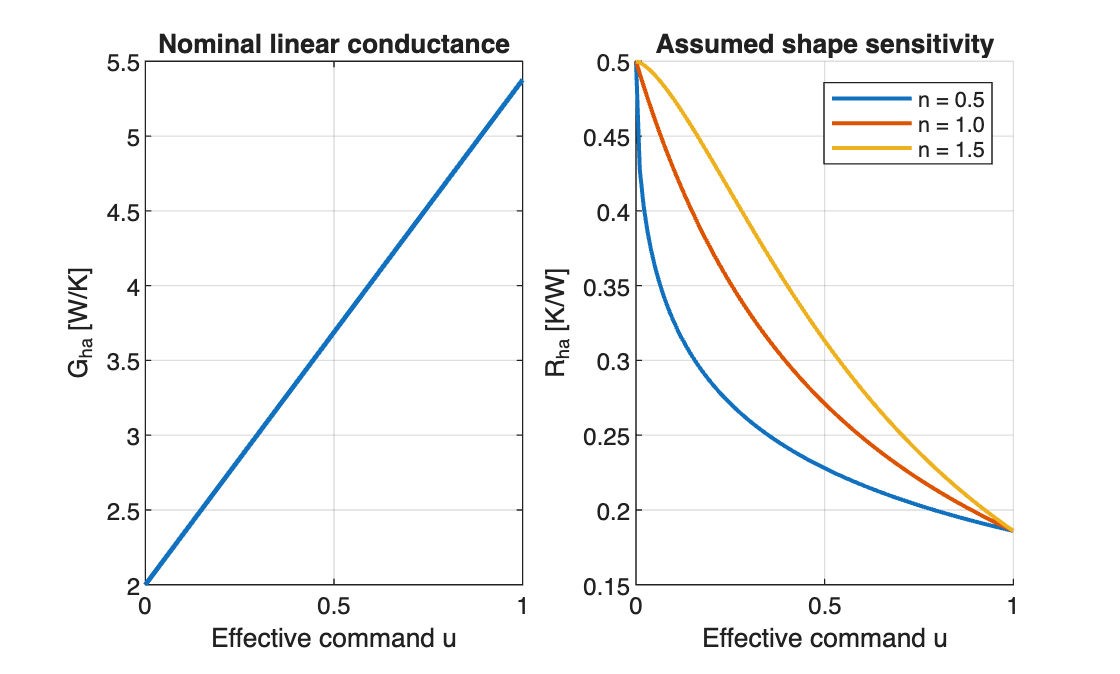


u_plot = linspace(0,1,101)';
figure('Name','Assumed fan cooling map','Color','w');
theme(gcf,'light');
tiledlayout(1,2,'TileSpacing','compact');
nexttile; plot(u_plot,G_of_u(u_plot),'LineWidth',1.8); grid on
xlabel('Effective command u'); ylabel('G_{ha} [W/K]');
title('Nominal linear conductance');
nexttile; hold on
for exponent = [0.5 1 1.5]
    G_curve = G_ha_passive + (G_ha_maxfan-G_ha_passive)*u_plot.^exponent;
    plot(u_plot,1./G_curve,'LineWidth',1.5, ...
        'DisplayName',sprintf('n = %.1f',exponent));
end
grid on; xlabel('Effective command u'); ylabel('R_{ha} [K/W]');
title('Assumed shape sensitivity'); legend('Location','northeast'); hold off

## 9. Steady-state checks and available cooling authority

For constant Q and u: Th,ss = Ta + Q Rha(u), and Te,ss = Ta + Q [Reh + Rha(u)]. The maximum steady heat load at the specified junction limit is Qlimit = (Tj,max − Ta)/(Reh + Rha). This is a model-derived threshold, not a manufacturer cooler rating.

Q_check = [Q_base; Q_turbo; Q_base; Q_turbo];
u_check = [1; 1; 0; 0];
Th_ss = T_a + Q_check .* R_of_u(u_check);
Te_ss = Th_ss + Q_check * R_eh;
steadyStateChecks = table( ...
    ["Maximum fan"; "Maximum fan"; "Stopped fan"; "Stopped fan"], ...
    Q_check, Th_ss, Te_ss, Tj_max-Te_ss, ...
    'VariableNames', {'Cooling','Power_W','Heatsink_degC','CPU_degC','MarginTo100_K'});
steadyStateChecks

steadyStateChecks = 4×5 table
       Cooling       Power_W    Heatsink_degC    CPU_degC    MarginTo100_K
    _____________    _______    _____________    ________    _____________

    "Maximum fan"      125          48.25          63.75          36.25   
    "Maximum fan"      181         58.666          81.11          18.89   
    "Stopped fan"      125           87.5            103             -3   
    "Stopped fan"      181          115.5         137.94        -37.944   


fprintf('Nominal maximum-fan threshold load: %.1f W\n', ...
    (Tj_max-T_a)/(R_eh+R_ha_maxfan));

Nominal maximum-fan threshold load: 241.9 W


fprintf('Nominal stopped-fan threshold load: %.1f W\n', ...
    (Tj_max-T_a)/(R_eh+R_ha_passive));

Nominal stopped-fan threshold load: 120.2 W


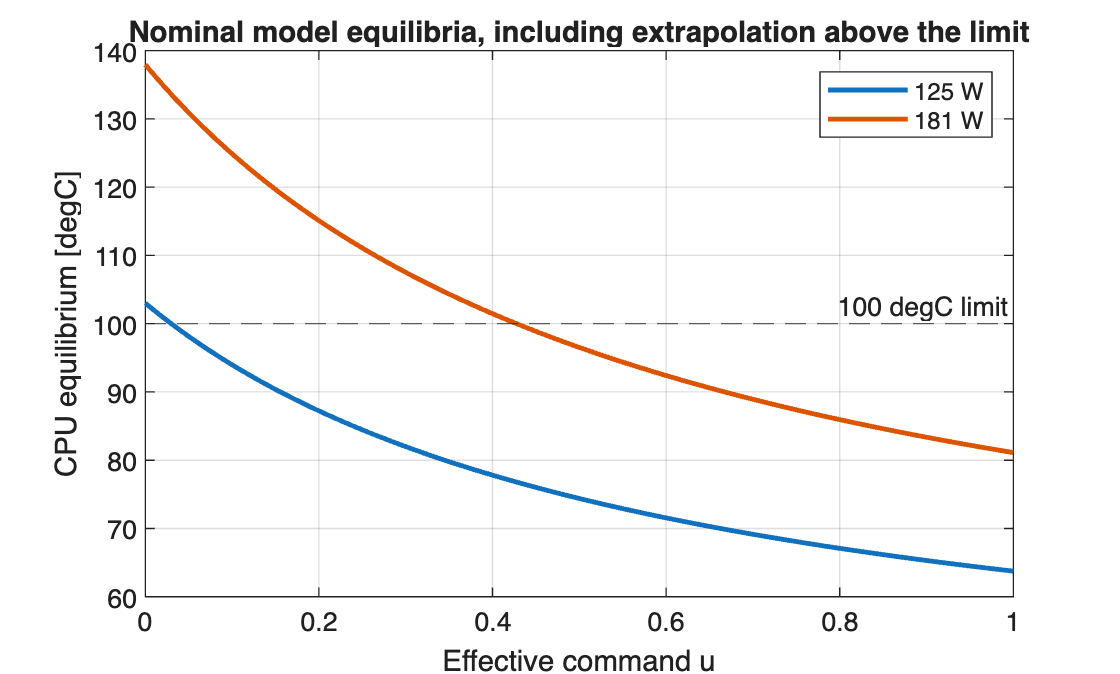


figure('Name','Steady-state cooling authority','Color','w');
theme(gcf,'light');
plot(u_plot,T_a+Q_base*(R_eh+R_of_u(u_plot)),'LineWidth',1.8);
hold on
plot(u_plot,T_a+Q_turbo*(R_eh+R_of_u(u_plot)),'LineWidth',1.8);
yline(Tj_max,'--','100 degC limit','HandleVisibility','off');
grid on; xlabel('Effective command u'); ylabel('CPU equilibrium [degC]');
title('Nominal model equilibria, including extrapolation above the limit');
legend('125 W','181 W','Location','northeast'); hold off

With these nominal assumptions, full-fan CPU equilibria are 63.75 °C at 125 W and 81.11 °C at 181 W. Stopped-fan equilibria exceed 100 °C at both loads. Values beyond the limit are algebraic extrapolations of the unthrottled equations; the transient plots stop at the first crossing. Matching 62 K at 200 W by construction is a consistency check, not independent validation.

A PI controller can only choose temperatures between the full-fan and stopped-fan equilibria for a fixed heat load. A setpoint below the full-fan equilibrium is unattainable. Controller tuning should include command saturation and anti-windup, then be revisited after the thermal parameters and actuator map are identified.

## 10. No-heatsink/no-fan comparison

Removing the cooler removes both Ch and the CPU-to-heatsink branch; it is not equivalent to setting u = 0 while retaining the heatsink. A finite-loss bare-package model would use Ce dTe/dt = Q − Gbare(Te − Ta), where Gbare includes exposed-package cooling and any retained socket path. Package outline dimensions alone do not determine Gbare or exposed IHS area.

No defensible Gbare value was established here. The implemented comparison is explicitly the adiabatic limit Gbare = 0: Ce dTe/dt = Q and Te(t) = Te0 + Qt/Ce. This is a zero-heat-removal limiting scenario, not a calibrated prediction for an exposed i5. For the same one-node Ce, Q and initial temperature, it gives the fastest heating among cases with nonnegative heat loss; it is not a guaranteed bound on actual die-temperature dynamics.

G_bare_adiabatic = 0;            % [W/K], deliberate limiting-case assumption
Q_bare = [Q_base; Q_turbo];
bareHeatingRate = Q_bare / C_e_nominal;
bareTimeToLimit = C_e_nominal*(Tj_max-T_e0) ./ Q_bare;
noHeatsinkComparison = table(Q_bare,bareHeatingRate,bareTimeToLimit, ...
    'VariableNames', {'Power_W','AdiabaticHeating_K_per_s','TimeTo100_s'});
noHeatsinkComparison

noHeatsinkComparison = 2×3 table
    Power_W    AdiabaticHeating_K_per_s    TimeTo100_s
    _______    ________________________    ___________

      125                6.402               11.715   
      181               9.2702               8.0905   


## 11. Transient demonstrations and warm fan failure

The plots compare a cold start with full fan, a stopped fan from the start, and the adiabatic no-heatsink limit. All start at 25 °C with the same Ce. The two-node constant-input solution is evaluated using the matrix exponential, requiring no Control System Toolbox. Each trace is truncated exactly at 100 °C if it crosses the limit.

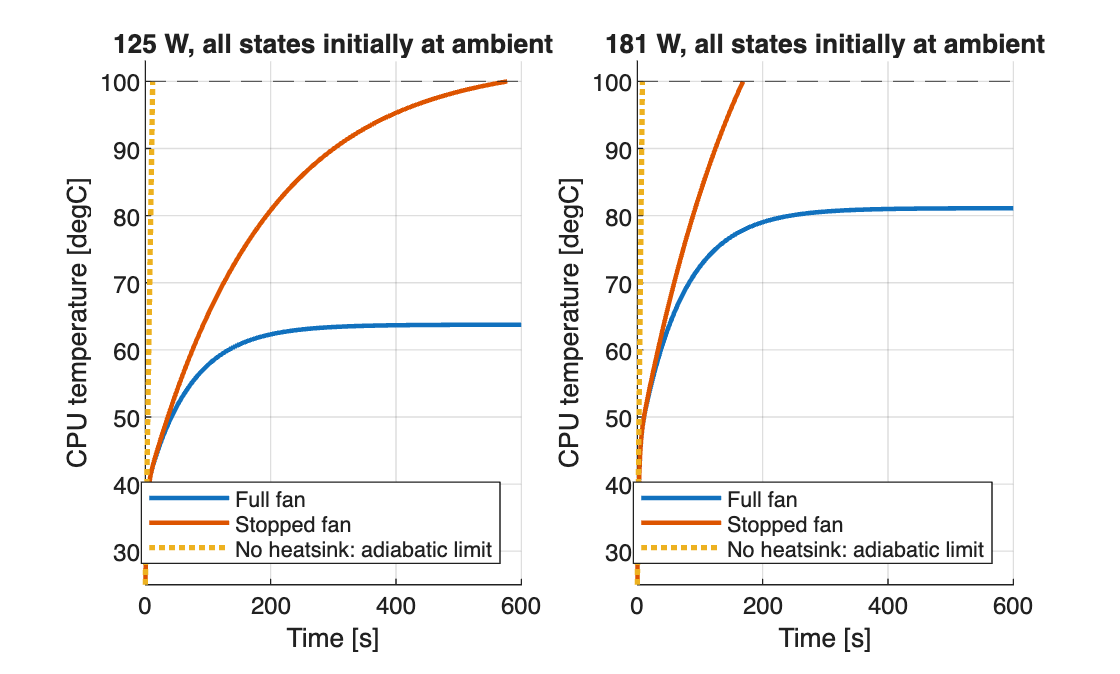

Q_cases = [Q_base Q_turbo];
figure('Name','Cold-start thermal scenarios','Color','w');
theme(gcf,'light');
tiledlayout(1,2,'TileSpacing','compact');
for k = 1:numel(Q_cases)
    Q_now = Q_cases(k);
    nexttile; hold on
    for mode = 1:2
        G_cases = [G_ha_maxfan G_ha_passive];
        labels = ["Full fan" "Stopped fan"];
        t_limit = tgTimeToLimit(Q_now,T_a,C_e_nominal,C_h_nominal, ...
            R_eh,G_cases(mode),[T_e0;T_h0],Tj_max);
        t_end = min(600,t_limit);
        t_grid = linspace(0,t_end,401)';
        T_grid = tgResponse(t_grid,Q_now,T_a,C_e_nominal,C_h_nominal, ...
            R_eh,G_cases(mode),[T_e0;T_h0]);
        plot(t_grid,T_grid(:,1),'LineWidth',1.7,'DisplayName',labels(mode));
    end
    t_bare = linspace(0,bareTimeToLimit(k),80)';
    plot(t_bare,T_e0+Q_now*t_bare/C_e_nominal,':','LineWidth',2, ...
        'DisplayName','No heatsink: adiabatic limit');
    yline(Tj_max,'--','HandleVisibility','off');
    ylim([T_a Tj_max+3]); grid on
    xlabel('Time [s]'); ylabel('CPU temperature [degC]');
    title(sprintf('%g W, all states initially at ambient',Q_now));
    legend('Location','southeast'); hold off
end


% A fan failure after warm operation is a different initial condition.
warmFailureTime = zeros(2,1);
warmCPU = zeros(2,1);
for k = 1:numel(Q_cases)
    Q_now = Q_cases(k);
    T_warm = T_a + Q_now*[R_eh+R_ha_maxfan; R_ha_maxfan];
    warmCPU(k) = T_warm(1);
    warmFailureTime(k) = tgTimeToLimit(Q_now,T_a,C_e_nominal,C_h_nominal, ...
        R_eh,G_ha_passive,T_warm,Tj_max);
end
warmFailure = table(Q_cases',warmCPU,warmFailureTime, ...
    'VariableNames', {'Power_W','CPUAtFanFailure_degC','TimeFromFailureTo100_s'});
warmFailure

warmFailure = 2×3 table
    Power_W    CPUAtFanFailure_degC    TimeFromFailureTo100_s
    _______    ____________________    ______________________

      125             63.75                    487.36        
      181             81.11                    78.523        


The warm-failure table starts from full-fan steady state and instantaneously switches to the stopped-fan conductance at the same load. These are assumption-dependent model times. Real power reduction, fan coast-down, spatial temperature gradients and sensor filtering can change them.

## 12. Sensitivity analysis: what is and is not established

These deterministic sweeps vary one assumption at a time. They are not statistical uncertainty intervals and do not exhaust all combinations. The full-fan steady CPU temperature depends on total resistance, but not on Ce or Ch. At fixed total resistance, changing α leaves that CPU equilibrium unchanged while changing heatsink temperature and transient modes. This is why a matching CPU steady temperature cannot validate the internal split.

**12.1 Resistance transfer and internal allocation**

The three published ratios are applied as alternative total-resistance scenarios solely to expose transfer sensitivity. They are not three validated i5 parameters and are not a fitted resistance-versus-power curve.

transferSensitivity = table(benchmarkData.BenchmarkCPU,R_benchmark, ...
    T_a+Q_base*R_benchmark,T_a+Q_turbo*R_benchmark, ...
    'VariableNames', {'RatioTakenFrom','AssumedTotal_K_per_W','CPU125_degC','CPU181_degC'});
transferSensitivity

transferSensitivity = 3×4 table
    RatioTakenFrom     AssumedTotal_K_per_W    CPU125_degC    CPU181_degC
    _______________    ____________________    ___________    ___________

    "Ryzen 5 3600"           0.58462             98.077         130.82   
    "Ryzen 7 3800X"          0.47154             83.943         110.35   
    "Ryzen 9 3950X"             0.31              63.75          81.11   



alpha_values = [0.2; alpha_eh; 0.6];
Reh_values = alpha_values * R_total;
Rha_values = (1-alpha_values) * R_total;
tau_split = zeros(numel(alpha_values),2);
for k = 1:numel(alpha_values)
    tau_split(k,:) = tgTimeConstants(C_e_nominal,C_h_nominal, ...
        Reh_values(k),1/Rha_values(k));
end
splitSensitivity = table(alpha_values,Reh_values,Rha_values, ...
    T_a+Q_turbo*(Reh_values+Rha_values),T_a+Q_turbo*Rha_values, ...
    tau_split(:,1),tau_split(:,2), ...
    'VariableNames', {'Alpha','Reh_K_per_W','Rha_K_per_W','CPU181_degC', ...
    'Heatsink181_degC','FastMode_s','SlowMode_s'});
splitSensitivity

splitSensitivity = 3×7 table
    Alpha    Reh_K_per_W    Rha_K_per_W    CPU181_degC    Heatsink181_degC    FastMode_s    SlowMode_s
    _____    ___________    ___________    ___________    ________________    __________    __________

     0.2        0.062          0.248          81.11            69.888           1.1471        93.566  
     0.4        0.124          0.186          81.11            58.666           2.2915        70.256  
     0.6        0.186          0.124          81.11            47.444           3.4287        46.954  


**12.2 Capacitance sensitivity**

For fixed fan command, the eigenvalues λ of the two-node state matrix give the two modal time constants τ = −1/λ. These are modes of the coupled system, not independent products assigned arbitrarily to each node. Ce and Ch are varied separately below. The adiabatic heating time is proportional to Ce, and all steady temperatures remain unchanged in this sweep.

Ce_sweep = [C_e_sensitivity'; C_e_nominal; C_e_nominal];
Ch_sweep = [repmat(C_h_nominal,3,1); C_h_min; C_h_max];
capCases = ["Ce x0.5"; "Nominal"; "Ce x2"; "Ch copper proxy"; "Ch aluminium proxy"];
tau_cap = zeros(numel(Ce_sweep),2);
for k = 1:numel(Ce_sweep)
    tau_cap(k,:) = tgTimeConstants(Ce_sweep(k),Ch_sweep(k),R_eh,G_ha_maxfan);
end
capacitanceSensitivity = table(capCases,Ce_sweep,Ch_sweep,tau_cap(:,1),tau_cap(:,2), ...
    Ce_sweep*(Tj_max-T_a)/Q_turbo, ...
    'VariableNames', {'Case','Ce_J_per_K','Ch_J_per_K','FastMode_s','SlowMode_s', ...
    'Adiabatic181W_TimeTo100_s'});
capacitanceSensitivity

capacitanceSensitivity = 5×6 table
            Case            Ce_J_per_K    Ch_J_per_K    FastMode_s    SlowMode_s    Adiabatic181W_TimeTo100_s
    ____________________    __________    __________    __________    __________    _________________________

    "Ce x0.5"                 9.7625        357.5         1.1778        68.344               4.0452          
    "Nominal"                 19.525        357.5         2.2915        70.256               8.0905          
    "Ce x2"                    39.05        357.5         4.3356        74.265               16.181          
    "Ch copper proxy"         19.525        214.5         2.2083        43.741               8.0905          
    "Ch aluminium proxy"      19.525        500.5          2.328        96.818               8.0905          


**12.3 Stopped-fan resistance and fan-map sensitivity**

Rpass_sweep = [0.30; R_ha_passive; 0.75; 1.00];
passiveTime = zeros(numel(Rpass_sweep),1);
T_warm181 = T_a+Q_turbo*[R_eh+R_ha_maxfan; R_ha_maxfan];
for k = 1:numel(Rpass_sweep)
    passiveTime(k) = tgTimeToLimit(Q_turbo,T_a,C_e_nominal,C_h_nominal, ...
        R_eh,1/Rpass_sweep(k),T_warm181,Tj_max);
end
passiveSensitivity = table(Rpass_sweep, ...
    T_a+Q_base*(R_eh+Rpass_sweep),T_a+Q_turbo*(R_eh+Rpass_sweep),passiveTime, ...
    'VariableNames', {'Rpassive_K_per_W','CPU125_degC','CPU181_degC','WarmFailure181W_s'});
passiveSensitivity

passiveSensitivity = 4×4 table
    Rpassive_K_per_W    CPU125_degC    CPU181_degC    WarmFailure181W_s
    ________________    ___________    ___________    _________________

           0.3                78         101.74            282.09      
           0.5               103         137.94            78.523      
          0.75            134.25         183.19             60.19      
             1             165.5         228.44            54.051      



exponent_sweep = [0.5; fan_exponent; 1.5];
G_half = G_ha_passive+(G_ha_maxfan-G_ha_passive)*0.5.^exponent_sweep;
fanShapeSensitivity = table(exponent_sweep,G_half,T_a+Q_turbo*(R_eh+1./G_half), ...
    'VariableNames', {'Exponent','ConductanceAtHalfCommand_W_per_K','CPU181AtHalf_degC'});
fanShapeSensitivity

fanShapeSensitivity = 3×3 table
    Exponent    ConductanceAtHalfCommand_W_per_K    CPU181AtHalf_degC
    ________    ________________________________    _________________

      0.5                    4.3874                      88.698      
        1                    3.6882                       96.52      
      1.5                    3.1937                      104.12      


**Interpretation.** The literature-transfer choice strongly changes steady-temperature predictions. The internal allocation and capacitances change dynamics even when full-fan equilibrium agrees. The assumed passive resistance can change whether a load remains below 100 °C, and substantially changes warm-failure time. The interpolation exponent changes the command required for regulation. Therefore a single fitted full-fan endpoint is insufficient to validate the controller plant.

## 13. Final nominal parameters and Simscape implementation

The table below is the single nominal parameter handoff. Manufacturer and material data are distinguished from assumed transfer, composition and dynamic parameters. The `_sim` variables preserve the original notebook's handoff naming. Derived conductances are included explicitly.

Q_base_sim = Q_base; Q_turbo_sim = Q_turbo;
T_a_sim = T_a; Tj_max_sim = Tj_max;             % [degC]
T_a_K_sim = T_a+273.15;                       % [K], absolute temperature
T_e0_K_sim = T_e0+273.15; T_h0_K_sim = T_h0+273.15;
C_e_sim = C_e_nominal; C_h_sim = C_h_nominal;
R_eh_sim = R_eh;
R_ha_passive_sim = R_ha_passive; R_ha_maxfan_sim = R_ha_maxfan;
G_ha_passive_sim = G_ha_passive; G_ha_maxfan_sim = G_ha_maxfan;
RPM_max_sim = RPM_max;
fan_exponent_sim = fan_exponent;
G_bare_adiabatic_sim = G_bare_adiabatic;

% Thermal Mass block: Mass type = Constant, C = Mass * Specific heat.
m_e_sim = m_cpu_assumed; cp_e_sim = C_e_sim/m_e_sim;
m_h_sim = m_hs; cp_h_sim = C_h_sim/m_h_sim;

simscapeParameters = table( ...
    ["Q_base"; "Q_turbo"; "T_a"; "Tj_max"; "C_e"; "C_h"; "R_total"; ...
     "R_eh"; "R_ha_passive"; "R_ha_maxfan"; "G_ha_passive"; "G_ha_maxfan"; ...
     "fan_exponent"; "RPM_max"; "G_bare_adiabatic"], ...
    [Q_base_sim; Q_turbo_sim; T_a_sim; Tj_max_sim; C_e_sim; C_h_sim; R_total; ...
     R_eh_sim; R_ha_passive_sim; R_ha_maxfan_sim; G_ha_passive_sim; ...
     G_ha_maxfan_sim; fan_exponent_sim; RPM_max_sim; G_bare_adiabatic_sim], ...
    ["W"; "W"; "degC"; "degC"; "J/K"; "J/K"; "K/W"; "K/W"; "K/W"; ...
     "K/W"; "W/K"; "W/K"; "1"; "rpm"; "W/K"], ...
    ["S1: specified test load"; "S1: specified test load"; "Assumed"; ...
     "S1: junction limit"; "Assumed mass + S4 material proxy"; ...
     "S2/S4 + assumed mass split"; "S3: assumed transfer to Intel"; ...
     "Assumed allocation of total"; "Assumed stopped-fan case"; ...
     "Assumed allocation of total"; "Reciprocal of assumed R"; ...
     "Reciprocal of assumed R"; "Assumed interpolation shape"; ...
     "S2: informational fan rating"; "Assumed adiabatic limit"], ...
    'VariableNames', {'Symbol','Value','Unit','Basis'});
simscapeParameters

simscapeParameters = 15×4 table
          Symbol          Value      Unit                   Basis               
    __________________    ______    ______    __________________________________

    "Q_base"                 125    "W"       "S1: specified test load"         
    "Q_turbo"                181    "W"       "S1: specified test load"         
    "T_a"                     25    "degC"    "Assumed"                         
    "Tj_max"                 100    "degC"    "S1: junction limit"              
    "C_e"                 19.525    "J/K"     "Assumed mass + S4 material proxy"
    "C_h"                  357.5    "J/K"     "S2/S4 + assumed mass split"      
    "R_total"               0.31    "K/W"     "S3: assumed transfer to Intel"   
    "R_eh"                 0.124    "K/W"     "Assumed allocation of total"     
    "R_ha_passive"           0.5    "K/W"     "Assumed stopped-fan case"        
    "R_ha_maxfan"          0.186    "K/W"     "Assumed allocation of total" 


thermalMassSettings = table(["CPU"; "Heatsink"],[m_e_sim; m_h_sim], ...
    [cp_e_sim; cp_h_sim],[T_e0_K_sim; T_h0_K_sim], ...
    'VariableNames', {'Block','Mass_kg','SpecificHeat_J_per_kgK','InitialTemperature_K'});
thermalMassSettings

thermalMassSettings = 2×4 table
      Block       Mass_kg    SpecificHeat_J_per_kgK    InitialTemperature_K
    __________    _______    ______________________    ____________________

    "CPU"         0.0355              550                     298.15       
    "Heatsink"      0.55              650                     298.15       


**Thermal masses [S6].** Set both Thermal Mass blocks to Constant mass. Enter the mass and specific heat from thermalMassSettings, and set the Temperature initial target to the listed value with high priority. The CPU mass/specific-heat pair is an equivalent parameterizations of the assumed Ce; it is not a measured CPU material composition. There is no need to enter a J/K value into a J/(kg·K) field.

**Heat paths [S7].** Use a Thermal Resistance block between the CPU and heatsink nodes with R_eh_sim in K/W. Between heatsink and ambient, use Variable Thermal Resistance and supply R = 1/[Gpassive + (Gmaxfan − Gpassive) u^n] to its physical input R in K/W. Clip the effective command to [0,1] upstream. A stopped-fan fault overrides the command to zero. Do not add another total CPU-to-air resistor in series with these two resistances.

**Sources and units.** A Controlled Heat Flow Rate Source injects the prescribed positive Q into the CPU node; verify the port orientation gives heating. Fix the ambient node at T_a_K_sim using a Temperature Source referenced to Thermal Reference. Include Solver Configuration for the physical network. Use W for the heat-flow converter, K/W for resistance, and an explicitly configured °C output (or subtract 273.15 from a K output) for the controller's temperature measurement.

**No-heatsink case.** Remove the heatsink mass and both cooler-path resistances. For the adiabatic limit, retain only the CPU mass and heat input, with zero heat loss. Do not insert a zero-K/W resistor: that would impose perfect conduction, the opposite of insulation. A later finite-loss exposed-package model needs independently justified Gbare.

## 14. Consistency checks and validation requirements

The following checks establish algebraic and physical consistency of this executable nominal model. They do not establish accuracy for the real processor. All parameters should be interpreted with the assumptions and sensitivity ranges above.

assert(all([C_e_sim C_h_sim R_eh_sim R_ha_maxfan_sim R_ha_passive_sim] > 0));
assert(R_ha_passive_sim > R_ha_maxfan_sim);
assert(abs(R_eh_sim+R_ha_maxfan_sim-R_total) < 1e-12);
assert(abs(G_of_u(0)-G_ha_passive_sim) < 1e-12);
assert(abs(G_of_u(1)-G_ha_maxfan_sim) < 1e-12);
assert(all(diff(G_of_u(u_plot)) > 0));
assert(abs(m_e_sim*cp_e_sim-C_e_sim) < 1e-12);
assert(abs(m_h_sim*cp_h_sim-C_h_sim) < 1e-12);

% At full-fan equilibrium both branch heat flows must equal CPU power.
T_equilibrium = T_a+Q_turbo*[R_eh+R_ha_maxfan; R_ha_maxfan];
qeh_check = (T_equilibrium(1)-T_equilibrium(2))/R_eh;
qha_check = G_ha_maxfan*(T_equilibrium(2)-T_a);
assert(max(abs([qeh_check qha_check]-Q_turbo)) < 1e-10);

% A cold-start response must tend to the analytical equilibrium.
tau_nominal = tgTimeConstants(C_e_sim,C_h_sim,R_eh,G_ha_maxfan);
T_late = tgResponse(20*max(tau_nominal),Q_turbo,T_a,C_e_sim,C_h_sim, ...
    R_eh,G_ha_maxfan,[T_e0;T_h0]);
assert(max(abs(T_late'-T_equilibrium)) < 1e-5);
fprintf('All nominal-model consistency checks passed.\n');

All nominal-model consistency checks passed.


**Measurements needed for validation.** Record CPU package power, cooler-inlet air temperature, a clearly defined CPU temperature metric, fan RPM/duty and a representative heatsink temperature on the same i5-13600K/NH-U12S redux assembly. At steady state, the two temperatures can estimate Reh ≈ (Te − Th)/Q and Rha ≈ (Th − Ta)/Q under the assumed dominant heat path. Account for sensor placement and any power bypassing the cooler.

Use power steps and fan-command steps to fit positive Ce, Ch and cooling-map parameters. Reserve separate runs for validation, reporting steady error, transient residuals, time-to-threshold where applicable, and repeatability across mounts. The AMD benchmark used to choose Rtotal cannot serve as an independent validation point. PI tuning and claims about fan-failure response remain provisional until that validation is available.

**Conclusion.** This document supplies a reproducible nominal plant, an explicit no-cooler limiting case, executable checks, and sensitivity results. It supports initial simulation and controller design while keeping manufacturer facts distinct from the assumptions that require measurement.

## 15. References and research record

All sources below were consulted on 4 October 2026. Reference IDs appear beside the inputs they support. No source in this list establishes the assumed resistance allocation, stopped-fan resistance, CPU effective capacitance, or fan-conductance interpolation.

[S1] Intel. [Intel Core i5-13600K Processor — Specifications](https://www.intel.com/content/www/us/en/products/sku/230493/intel-core-i513600k-processor-24m-cache-up-to-5-10-ghz/specifications.html). CPU Specifications: 125 W base and 181 W maximum turbo power. Package Specifications: TJUNCTION 100 °C and package size 45.0 × 37.5 mm. No lumped Ce or CPU mass is listed on this specification page.

[S2] Noctua. [NH-U12S redux information sheet](https://cdn.noctua.at/media/noctua_nh_u12s_redux_infosheet_en_web.pdf), p. 1, heatsink and fan specifications. Supports 550 g without fan; copper base/heatpipes and aluminium fins; 1700 rpm ±10%; 120.2 m³/h; 2.83 mmH2O; maximum electrical input 1.08 W. No constituent mass split or passive K/W rating is supplied there.

[S3] Burke, S. and Gaglione, M., GamersNexus. [$50 Noctua Air Cooler Review: NH-U12S Redux vs. Stock AMD Coolers & More](https://gamersnexus.net/coolers/50-noctua-air-cooler-review-nh-u12s-redux-vs-stock-amd-coolers-more). Original 2021 review, written page updated 23 June 2024. See CPU Cooler Test Bench and the 65 W, 123 W and 200 W sections at 100% fan speed: approximately 38 K, 58 K and 62 K above ambient on different AMD processors. Nominal ambient in the review is around 21 °C; the model's 25 °C ambient is a separate assumption.

[S4] Engineering ToolBox (2003). [Metals — Specific Heats](https://www.engineeringtoolbox.com/specific-heat-metals-d_152.html), table rows Aluminium, Copper and Silicon. Rounded values 0.91, 0.39 and 0.71 kJ/(kg·K). Used as approximate constant material data; no CPU/cooler-specific composition is implied.

[S5] Noctua. [PWM specifications white paper](https://cdn.noctua.at/media/Noctua_PWM_specifications_white_paper.pdf), pp. 6–7: PWM signal definition, broadly linear RPM behaviour over the specified control range, behaviour below 20%, and full-speed operation when no PWM signal is present. This document does not specify a thermal-conductance-versus-duty curve.

[S6] MathWorks. [Thermal Mass](https://www.mathworks.com/help/simscape/ref/thermalmass.html). Implementation checked against the installed R2026a Foundation Library source: toolbox/physmod/simscape/library/m/+foundation/+thermal/+elements/mass.ssc, Constant mass equation Q = mass × sp_heat × dT/dt. Supports the mass/specific-heat mapping and Temperature initial target.

[S7] MathWorks. [Thermal Resistance](https://www.mathworks.com/help/simscape/ref/thermalresistance.html) and [Variable Thermal Resistance](https://www.mathworks.com/help/simscape/ref/variablethermalresistance.html). The variable block was also checked against installed R2026a source +foundation/+thermal/+elements/variable_resistance.ssc: physical input R has units K/W and is limited by Minimum thermal resistance.

## Computational appendix — constant-input two-node solution

For fixed Q and G, define x = [Te; Th]. Then dx/dt = A(x − xss), where xss = Ta + Q[Reh + 1/G; 1/G]. Thus x(t) = xss + exp(A t)(x0 − xss). The functions below evaluate this solution, its modal time constants, and the first threshold crossing for the monotonic cold-start/warm-failure cases used above. Inf means the equilibrium does not cross the limit from below.

function A = tgMatrix(Ce,Ch,Reh,G)
    A = [-1/(Ce*Reh), 1/(Ce*Reh); ...
          1/(Ch*Reh), -(1/Reh+G)/Ch];
end

function T = tgResponse(t,Q,Ta,Ce,Ch,Reh,G,T0)
    A = tgMatrix(Ce,Ch,Reh,G);
    Tss = Ta + Q*[Reh+1/G; 1/G];
    T = zeros(numel(t),2);
    for j = 1:numel(t)
        T(j,:) = (Tss+expm(A*t(j))*(T0(:)-Tss))';
    end
end

function tau = tgTimeConstants(Ce,Ch,Reh,G)
    lambda = eig(tgMatrix(Ce,Ch,Reh,G));
    assert(all(real(lambda)<0) && all(abs(imag(lambda))<1e-10));
    tau = sort(-1./real(lambda))';
end

function tLimit = tgTimeToLimit(Q,Ta,Ce,Ch,Reh,G,T0,Tlimit)
    if T0(1) >= Tlimit
        tLimit = 0;
        return
    end
    Tss = Ta+Q*[Reh+1/G; 1/G];
    if Tss(1) <= Tlimit
        tLimit = Inf;
        return
    end
    A = tgMatrix(Ce,Ch,Reh,G);
    residual = @(t) [1 0]*(Tss+expm(A*t)*(T0(:)-Tss))-Tlimit;
    upper = max(tgTimeConstants(Ce,Ch,Reh,G));
    while residual(upper) < 0
        upper = 2*upper;
        assert(isfinite(upper),'Could not bracket the threshold crossing.');
    end
    tLimit = fzero(residual,[0 upper]);
end